Name    : Pranay Borgohain

Roll No. : 20EE01015

# **Digital Signal Processing Laboratory Experiment - 4**

% Defining some common functions to be used in this experiment
delta = @(n) n == 0;

% making the value of heaviside() at origin equal to 1
sympref('HeavisideAtOrigin', 1);
u = @(n) heaviside(n);

% defining the DTFT function
dtft = @(xn, n, w) xn * exp(-1j .* (n' * w));

% defining discrete time Inverse Fourier Transform
dtift = @(Xw, w, n) Xw * exp(1j .* (w' * n));

% defining range of frequencies (omega) from -pi to +pi
w = -pi:0.01:pi;

**Q1:**

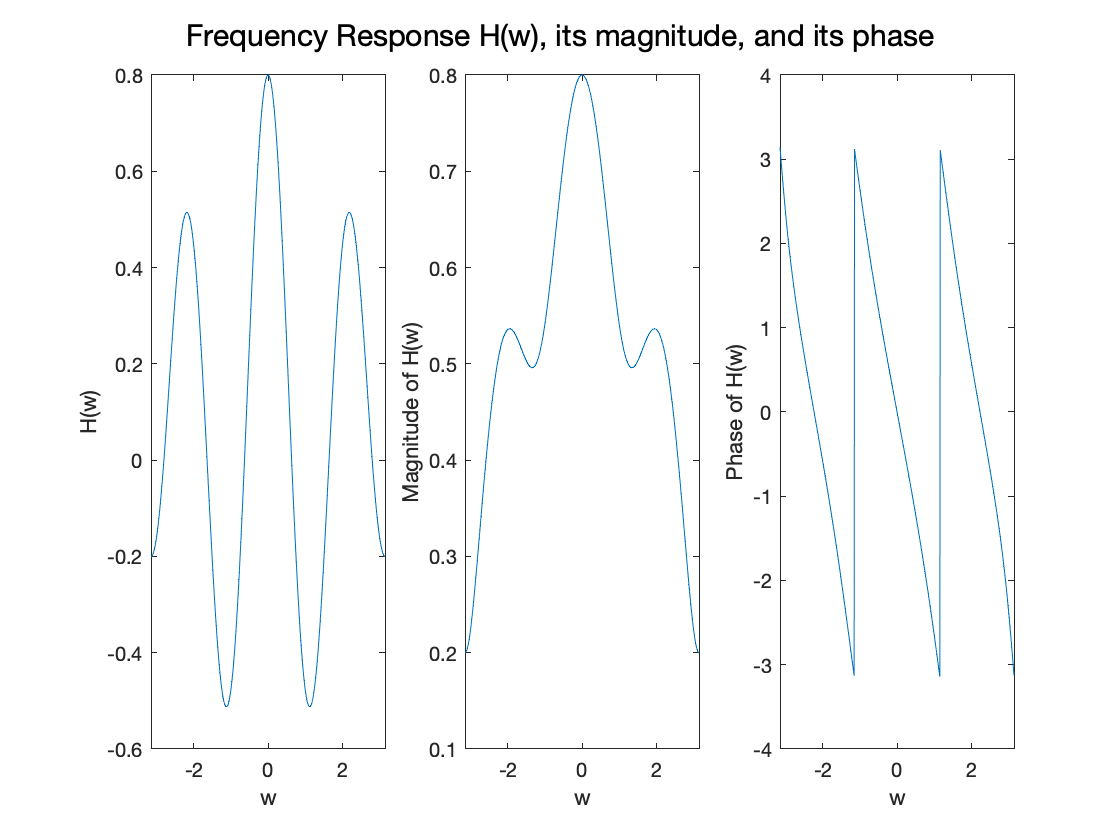

h = @(n) (0.1 * delta(n)) + (0.2 * delta(n-2)) + (0.5 * delta(n-3));
n = -1:4;

H = dtft(h(n), n, w);

% plotting the frequency response along with its magnitude and phase
figure;
subplot(1, 3, 1);
plot(w, real(H));
xlabel("w"); ylabel("H(w)");

subplot(1, 3, 2);
plot(w, abs(H));
xlabel("w"); ylabel("Magnitude of H(w)");

subplot(1, 3, 3);
plot(w, angle(H));
xlabel("w"); ylabel("Phase of H(w)");
sgtitle("Frequency Response H(w), its magnitude, and its phase");

Q2:


$$y(n) + 0.1y(n-1) + 0.2y(n-2) = x(n)$$


Applying Fourier Transform, we get:


$$\Rightarrow Y(\omega) + 0.1Y(\omega)\cdot e^{-j\omega} + 0.2Y(\omega)\cdot e^{-j2\omega} = X(\omega)$$



$$\Rightarrow Y(\omega)\cdot(1 + 0.1e^{-j\omega} + 0.2e^{-j2\omega}) = X(\omega)$$


Therefore,


$$\Rightarrow H(\omega) = \frac{Y(\omega)}{X(\omega)} = \frac{1}{1 + 0.1e^{-j\omega} + 0.2e^{-j2\omega}}$$


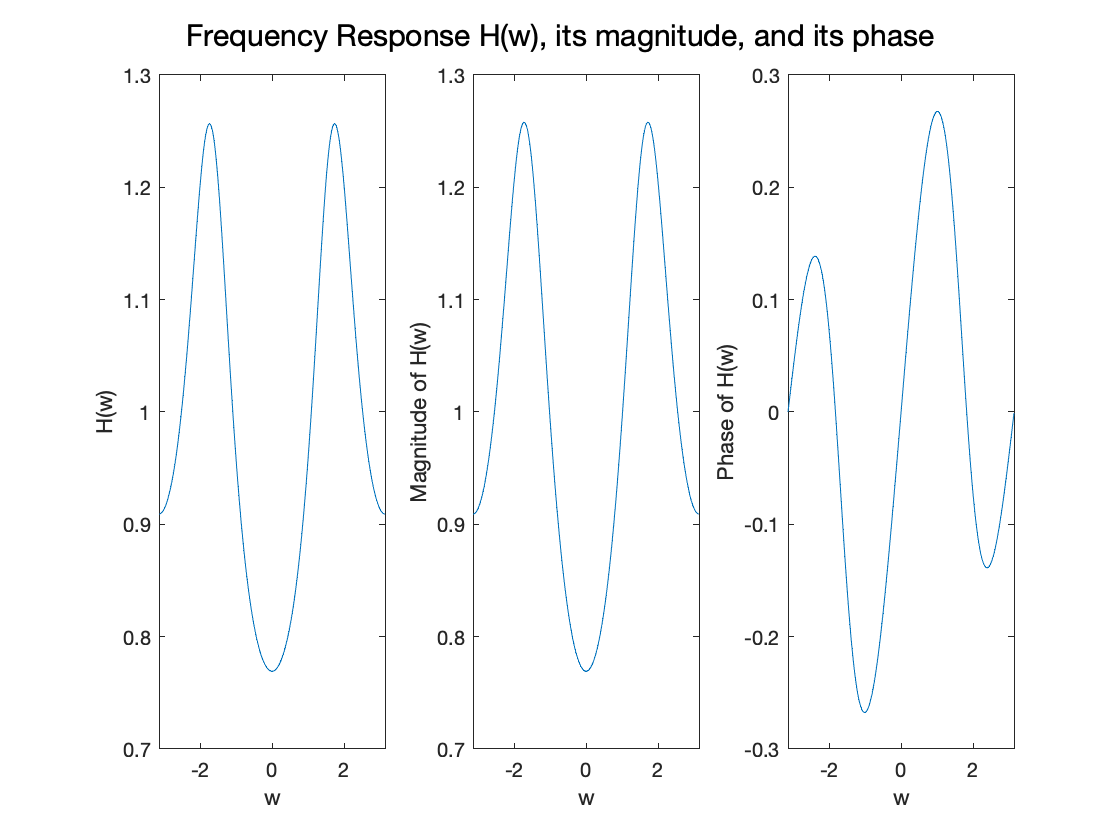

% defining the frequency response in terms of the above equation
H = @(w) 1 ./ (1 + 0.1 .* exp(-1i .* w) + 0.2 .* exp(-2i .* w));

Hw = H(w);

% plotting frequency response, magnitude, phase
figure;
subplot(1, 3, 1);
plot(w, real(Hw));
xlabel("w"); ylabel("H(w)");

subplot(1, 3, 2);
plot(w, abs(Hw));
xlabel("w"); ylabel("Magnitude of H(w)");

subplot(1, 3, 3);
plot(w, angle(Hw));
xlabel("w"); ylabel("Phase of H(w)");
sgtitle("Frequency Response H(w), its magnitude, and its phase");

Q3:

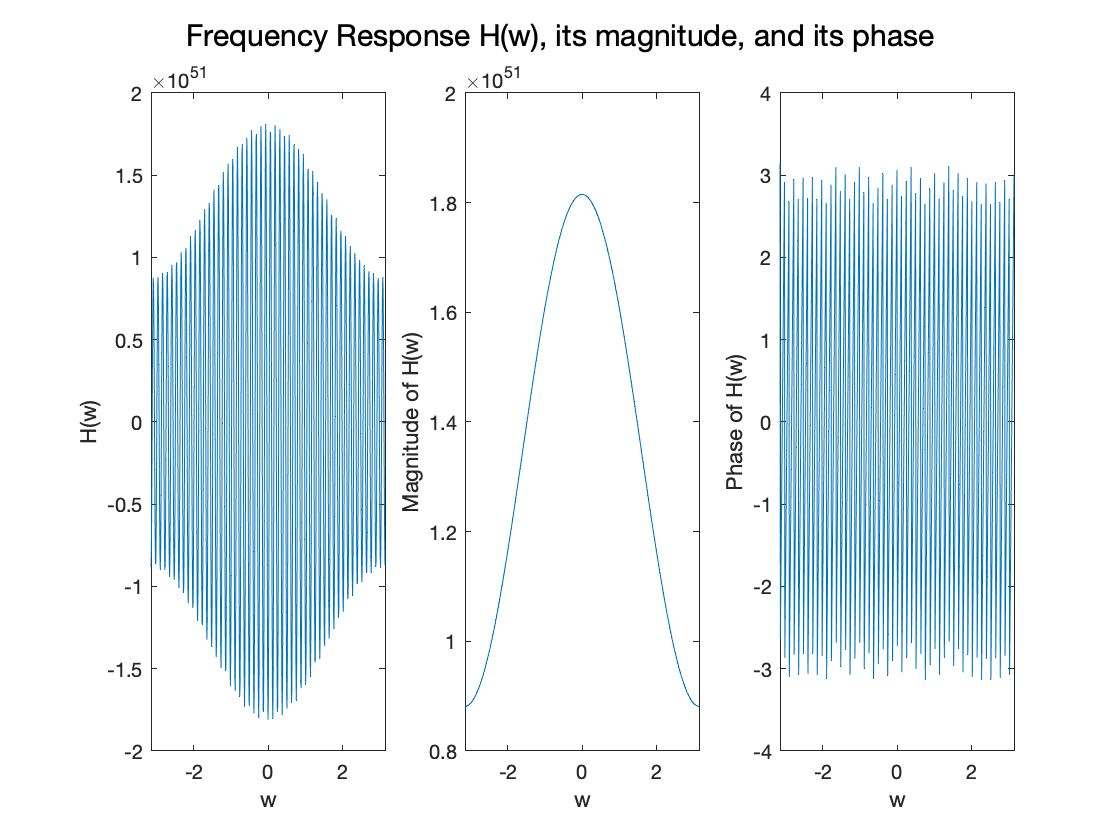

h = @(n) n .* ((0.1) .^ n) .* sin(n);
n = -50:50;

H = dtft(h(n), n, w);

% plotting frequency response, magnitude, phase
figure;
subplot(1, 3, 1);
plot(w, real(H));
xlabel("w"); ylabel("H(w)");

subplot(1, 3, 2);
plot(w, abs(H));
xlabel("w"); ylabel("Magnitude of H(w)");

subplot(1, 3, 3);
plot(w, angle(H));
xlabel("w"); ylabel("Phase of H(w)");
sgtitle("Frequency Response H(w), its magnitude, and its phase");

Q4:

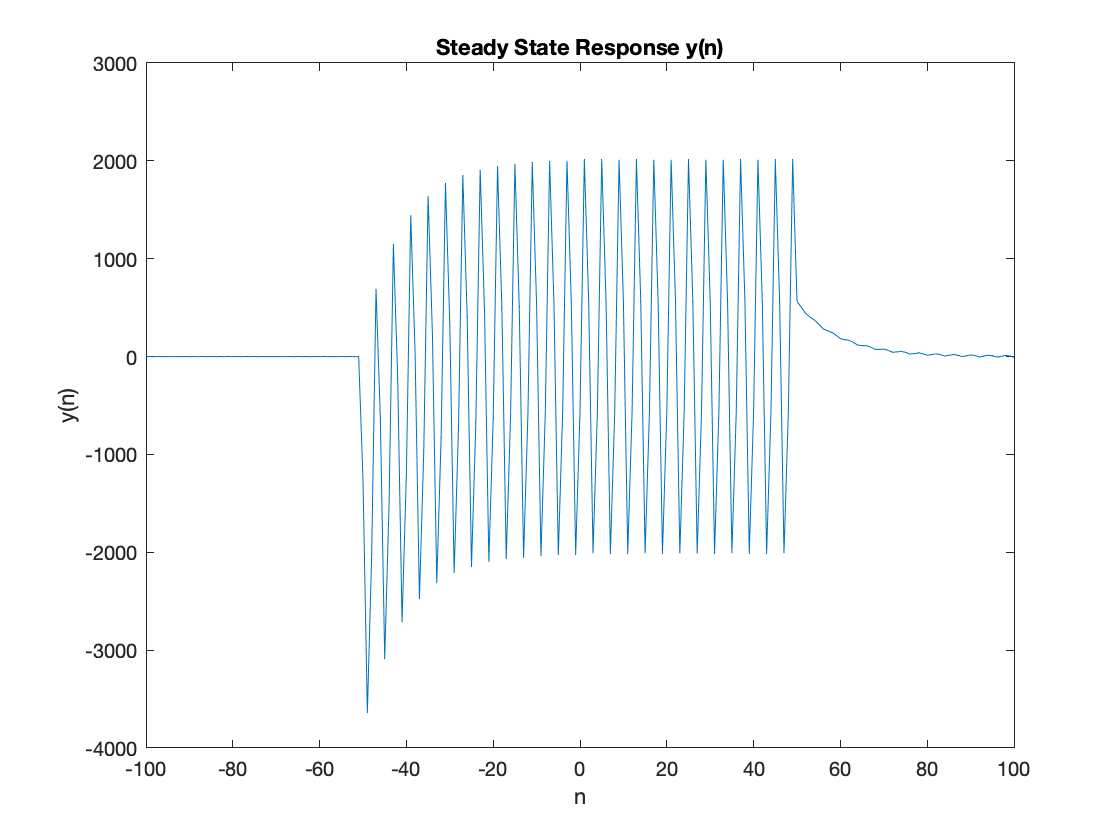

h = @(n) ((0.9) .^ n) .* u(n);
x = @(n) 2*cos(pi .* n ./ 2) + 4*sin(pi .* n ./ 2);

% range of inputs for x(n) and h(n)
n1 = -50:50;
% range of inputs for y(n)
n2 = -100:100;

H = dtft(h(n1), n1, w);
X = dtft(x(n1), n1, w);
Y = X .* H;
y = dtift(Y, w, n2);

figure;
plot(n2, real(y));
xlabel("n"); ylabel("y(n)"); title("Steady State Response y(n)");

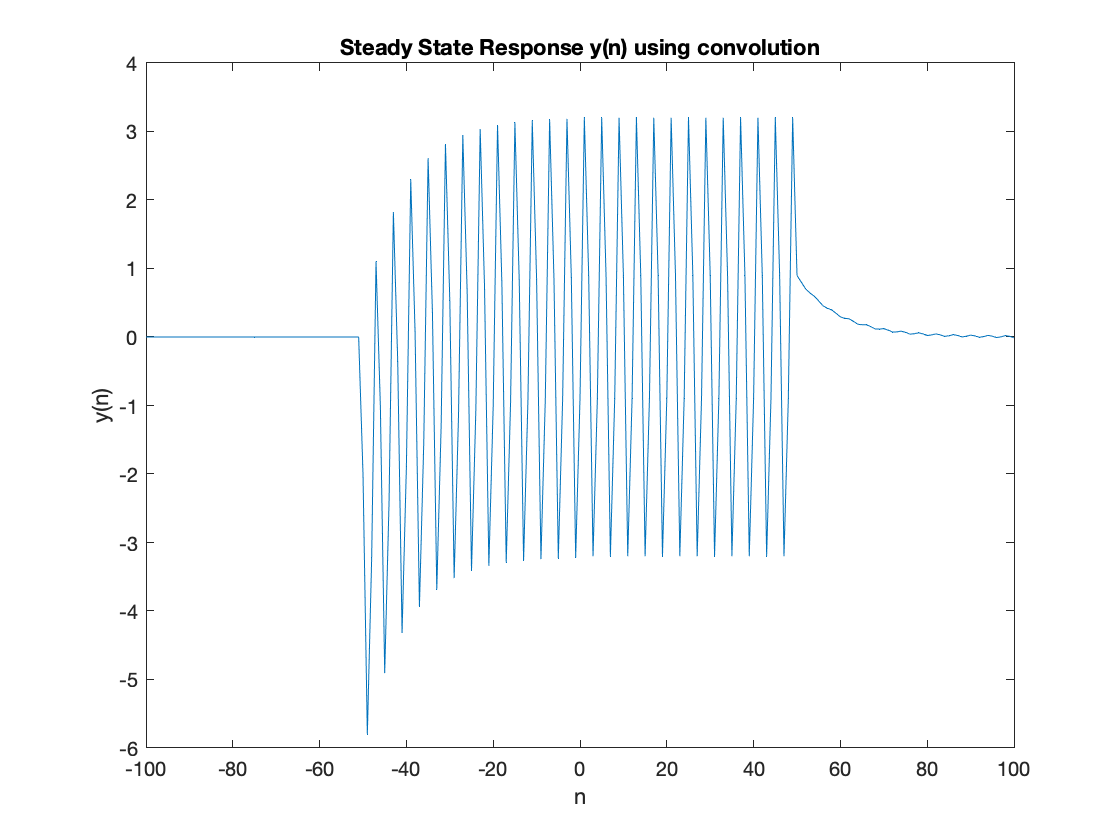

figure;
plot(n2, conv(x(n1), h(n1)));
xlabel("n"); ylabel("y(n)"); title("Steady State Response y(n) using convolution");

On comparing the above two plots, we find that they are equivalent in nature. Hence, we have accurately obtained the steady state response y(n) since the results obtained using convolution and fourier transform are similar.

Q5:

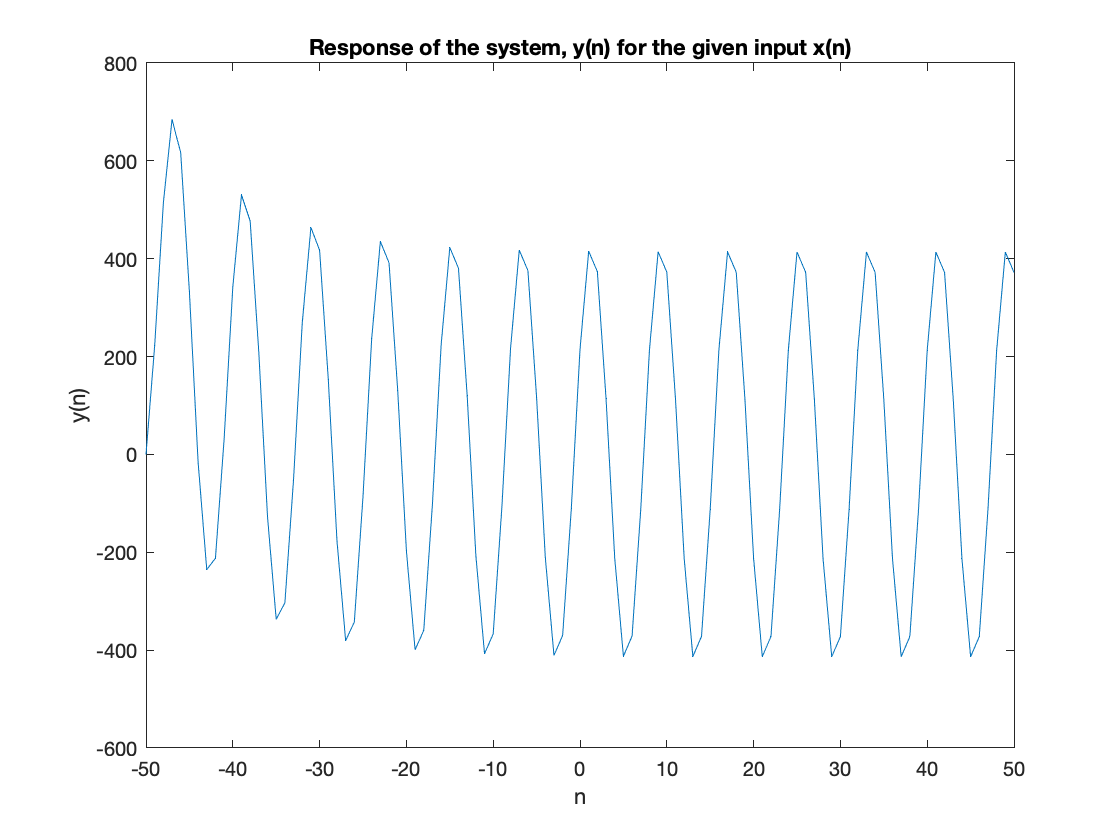

H = @(w) 1 ./ (1 - 0.9*exp(-1i * w));
x = @(n) 0.5 .* cos(pi * n ./ 4);
n = -50:50;

X = dtft(x(n), n, w);
Y = X .* H(w);
y = dtift(Y, w, n);

figure;
plot(n, real(y));
xlabel("n"); ylabel("y(n)"); title("Response of the system, y(n) for the given input x(n)");

Q6:


$$y_1(n)+ 0.1y_1(n-1) = x(n)$$


Using Fourier Transform,


$$\Rightarrow Y_1(\omega) + 0.1Y_1(\omega)\cdot e^{-j\omega} = X(\omega)$$



$$\Rightarrow H_1(\omega) = \frac{Y(\omega)}{X(\omega)} = \frac{1}{1 + 0.1e^{-j\omega}}$$



$$y_2(n) + 0.1y_2(n-1) + 2y_2(n-2) = x(n)$$


Similarly,


$$\Rightarrow H_2(\omega) = \frac{1}{1 + 0.1e^{-j\omega} + 2e^{-j2\omega}}$$


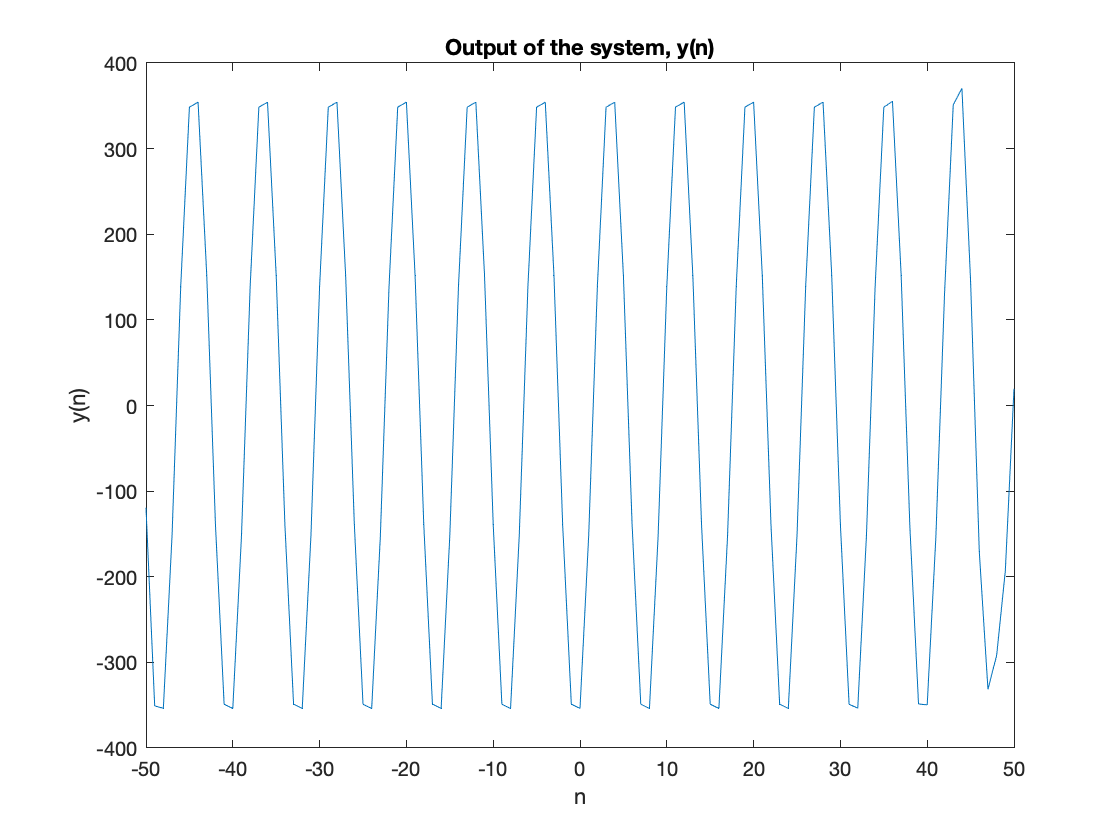

% Using the above equations
H1 = @(w) 1 ./ (1 + 0.1*exp(-1i * w));
H2 = @(w) 1 ./ (1 + 0.1*exp(-1i * w) + 2*exp(-2i * w));

% Since the systems are in parallel, the frequency response of the 
% overall system would be the sum of individual frequency responses
H = @(w) H1(w) + H2(w);

x = @(n) 0.5 .* cos((pi * n ./ 4) - pi);
n = -50:50;

X = dtft(x(n), n, w);
Y = X .* H(w);
y = dtift(Y, w, n);

figure;
plot(n, real(y));
xlabel("n"); ylabel("y(n)"); title("Output of the system, y(n)");